# NACA airfoil wing model

Finite element model from the following reference:

Jain, S., Tiso, P., Rutzmoser, J. B., & Rixen, D. J. (2017). A quadratic manifold for model order reduction of nonlinear structural dynamics. *Computers & Structures*, *188*, 80–94. [https://doi.org/10.1016/J.COMPSTRUC.2017.04.005](https://doi.org/10.1016/J.COMPSTRUC.2017.04.005)

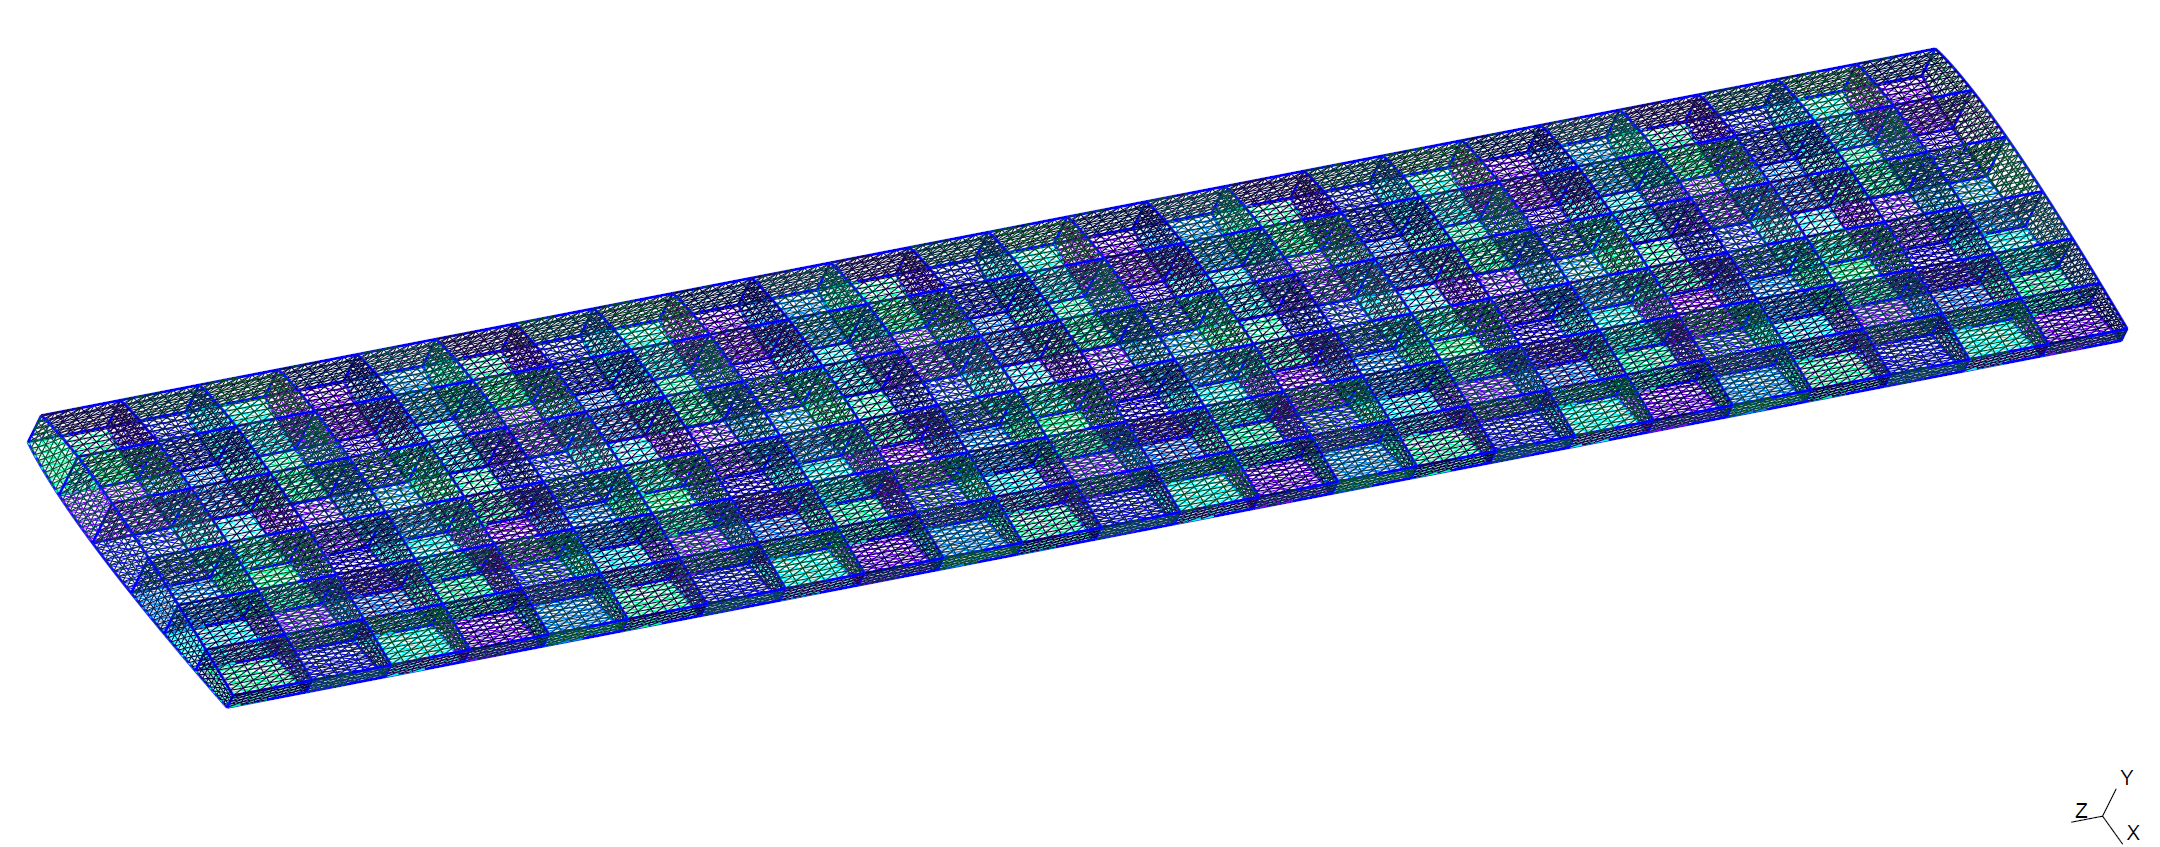

Finite element code taken from the following package:

Jain, S., Marconi, J., Tiso P. (2020). YetAnotherFEcode (Version v1.1). Zenodo. [http://doi.org/10.5281/zenodo.4011282](http://doi.org/10.5281/zenodo.4011282)

**system parameters**

clear all;
clc;
epsilon  = 0.1;

## generate model

[M,C,K,fnl,f_0,outdof] = build_model();

Reading mesh from Wing.msh
Building FE model
Assembling M,C,K matrices
Applying boundary conditions
Solving undamped eigenvalue problem


ans =   Patch (Deformed Mesh) - 属性:

    FaceColor: 'interp'
    FaceAlpha: 1
    EdgeColor: [0 0 0]
    LineStyle: '-'
        Faces: [49968×3 double]
     Vertices: [149904×3 double]

  显示 所有属性

Using Rayleigh damping
Assembling external force vector
Getting nonlinearity coefficients
Assembling Tensors


% load("M.mat","M")
% load("C.mat","C")
% load("K.mat","K")
% load("fnl.mat","fnl")
% load("f_0.mat","f_0")
% load("outdof.mat","outdof")

n = length(M);
disp(['Number of degrees of freedom = ' num2str(n)])
disp(['Phase space dimensionality = ' num2str(2*n)])

## Dynamical system setup 

We consider the forced system


$$\mathbf{M}\ddot{\mathbf{x}}+\mathbf{C}\dot{\mathbf{x}}+\mathbf{K}\mathbf{x}+\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})=\epsilon\mathbf{f}^{ext}(\mathbf{\Omega}t),$$


which can be written in the first-order form as 


$$\mathbf{B}\dot{\mathbf{z}}	=\mathbf{Az}+\mathbf{F}(\mathbf{z})+\epsilon\mathbf{F}^{ext}(\mathbf{\phi}),\\\dot{\mathbf{\phi}}	
=\mathbf{\Omega}$$


where

$\mathbf{z}=\left[\begin{array}{c}\mathbf{x}\\\dot{\mathbf{x}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}-\mathbf{K} 
& \mathbf{0}\\\mathbf{0} & \mathbf{M}\end{array}\right],\mathbf{B}=\left[\begin{array}{cc}\mathbf{C} 
& \mathbf{M}\\\mathbf{M} & \mathbf{0}\end{array}\right],\quad\quad\mathbf{F}(\mathbf{z})=\left[\begin{array}{c}\mathbf{-\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})}\\\mathbf{0}\end{array}\right],\quad\mathbf{F}^{ext}(\mathbf{z},\mathbf{\phi})=\left[\begin{array}{c}
\mathbf{f}^{ext}(\mathbf{\phi})\\
\mathbf{0}
\end{array}\right]$.

DS = DynamicalSystem();
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',5,'Nmax',10,'notation','multiindex')
% set(DS.Options,'Emax',5,'Nmax',10,'notation','tensor')

We assume periodic forcing of the form


$$\mathbf{f}^{ext}(\phi) = \mathbf{f}_0\cos(\phi)=\frac{\mathbf{f}_0}{2}e^{i\phi} + \frac{\mathbf{f}_0}{2}e^{-i\phi}  $$


Fourier coefficients of Forcing

kappas = [-1; 1];
coeffs = [f_0 f_0]/2;
DS.add_forcing(coeffs, kappas,epsilon);

## Linear Modal analysis and SSM setup

[V,D,W] = DS.linear_spectral_analysis();
% load("V.mat","V")
% load("D.mat","D")
% load("W.mat","W")

**Choose Master subspace (perform resonance analysis)**

S = SSM(DS);
set(S.Options, 'reltol', 0.1,'notation','multiindex')
% set(S.Options, 'reltol', 0.1,'notation','tensor')
masterModes = [1,2]; 
S.choose_E(masterModes);

## Forced response curves using SSMs

Obtaining **forced response curve** in reduced-polar coordinate

order = 3; % Approximation order
% [W_0,R_0] = S.compute_whisker(order);
load("W_0.mat","W_0")
load("R_0.mat","R_0")

setup options

set(S.Options, 'reltol', 1,'IRtol',0.02,'notation', 'multiindex','contribNonAuto',false)
set(S.FRCOptions, 'nt', 2^7, 'nRho', 200, 'nPar', 200, 'nPsi', 100, 'rhoScale', 2 )
% set(S.FRCOptions, 'method','level set')
set(S.FRCOptions, 'method','continuation ep', 'z0', 1e-4*[1; 1])
set(S.FRCOptions, 'outdof',outdof)

Bext     = zeros(n,2); Bext(outdof(1),1)=1; Bext(outdof(2),2)=1; 
% epsilon  = 0.1;
set(DS,'D',Bext,'epsilon',epsilon);
set(DS.Options, 'outDOF', outdof);

% tic
% z0 = GetInitialz0Bysyatic(DS,0.0001,100);
% toc
% z0 = [z0; zeros(size(z0))];


choose frequency range around the first natural frequency

% omega0 = imag(S.E.spectrum(1));
% omegaRange = omega0*[0.9 1.1];

extract forced response curve

% FRC = S.extract_FRC('freq',omegaRange,order);
% figFRC = gcf;


## LQR control

% z0 = [zeros(n,1); zeros(n,1)]; % random initial condition
load("z0_static3.mat","z0")
% load("z0_static.mat","z0")
% z0 = [z0; zeros(size(z0))];

auData = construct_autoData(DS, masterModes, R_0);
tf     = 1; nsteps = 5000;
tspan  = linspace(0,tf,nsteps);
cont   = struct();
cont.Q    = 1e4*speye(2*n);
cont.Rhat = 100*speye(2);
cont.Mhat = 0e1*speye(2*n); 

## Cutoff Criteria

% res = Cutof_LQR_closed_loop_MT2_comp(DS,50)



% traj_closed1 = NACAWing_LQR(DS,z0,'nonlinear',tspan,auData,W_0,masterModes,1:2,cont);

% % % traj_closed3 = LQR_closed_loop_BT(DS,z0,'linear',tspan,auData,W_0,masterModes,cont);
% % nsteps = 8000;
% % tf     = 1; nsteps = 3000;
om = 2*pi/tf;
set(DS,'u',[]);
[tfullwo, xfullwo] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','Newmark','outdof',outdof,'init',z0);

% % om = 2*pi/tf;
% ufun = @(t) transpose(interp1(traj_closed1.time,traj_closed1.ut',t,'linear','extrap'));
% set(DS,'u',ufun);
% [tfullwc, xfullwc] = time_integration_transient(DS,om,'nCycles',...
%     1, 'nSteps', nsteps,...
%     'integrationMethod','Newmark','outdof',outdof,'init',z0);


## Plot zt


% figure; hold on
% plot(traj_closed1.time, traj_closed1.zt(2,:),'b--','DisplayName','SSM-closed-control');
% % plot(traj_closed2.time, traj_closed2.zt(1,:),'m--','DisplayName','SSM-closed-control-MT');
% % % plot(traj_closed3.time, traj_closed3.zt(1,:),'k--','DisplayName','SSM-closed-control-BT');
% % load("xfullwo.mat","xfullwo")
% % load("tfullwo.mat","tfullwo")
% plot(tfullwo, xfullwo(:,1),'k-','DisplayName','Full-without-control');
% plot(tfullwc, xfullwc(:,1),'r-.','DisplayName','Full-with-control');
% xlabel('$t$','Interpreter',"latex")
% zk = strcat('$w(t)$');
% ylabel(zk,'Interpreter','latex');
% title('2D Reduction')
% set(gca,'FontSize',14);
% grid on, axis tight
% legend('show'); legend boxoff
% set(gca,'FontSize',14); grid on, axis tight
% 

## Plot ut

% 
% figure; hold on;
% % plot(traj_closed1.time,traj_closed1.ut);
% plot(traj_closed2.time,traj_closed2.ut);
% xlabel('$t$','Interpreter',"latex")
% ylabel('$u$','Interpreter','latex')
% legend('u1','u2')
% legend('show'); legend boxoff
% set(gca,'FontSize',14); grid on, axis tight

## LQR 2 SEGS

nsteps = 2500;
t0 = 0;
t1 = 0.5;
tspan1 = linspace(t0,t1,nsteps);
tic
traj1   = NACAWing_LQR(DS,z0,'linear',tspan1,auData,W_0,masterModes,1:2,cont);
toc

ufun  = @(t) transpose(interp1(traj1.time,traj1.ut',t,'linear','extrap'));
    set(DS,'u',ufun);
tic
[tfull1, xfull1, xkf,xt1] = time_integration_transient(DS,2*pi/(t1-t0),'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','Newmark','outdof',outdof,'init',z0,'ts',t0);
toc 

xf = xkf';
% load("xt1.mat","xt1")
% xf  =  xt1(end,:)';
t2 = 1;
tspan2 = linspace(t1,t2,nsteps);
tic 
traj2   = NACAWing_LQR(DS,xf,'linear',tspan2,auData,W_0,masterModes,1:2,cont);
toc

ufun  = @(t) transpose(interp1(traj2.time,traj2.ut',t,'linear','extrap'));
    set(DS,'u',ufun);
tic
[tfull2, xfull2, xkf, xt2] = time_integration_transient(DS,2*pi/(t2-t1),'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','Newmark','outdof',outdof,'init',xf,'ts',t1);
toc



% zt1 = traj1.zt;
% zt2 = traj2.zt;
% 
% zauto1 = traj1.zt_auto;
% zauto2 = traj2.zt_auto;

## PLOT


% figure; hold on
% for k=1:nint
%     plot(trajs{k}.time, trajs{k}.zt(1,:),'r-');
%     % plot(trajs{k}.time, trajs{k}.zt_auto(1,:),'k-.');
%     plot(tfullc{k}, xfullc{k}(:,1),'b-');
% end
% load("xfullwo.mat","xfullwo")
% load("tfullwo.mat","tfullwo")
% plot(tfullwo, xfullwo(:,1),'k-');
% xlabel('$t$','Interpreter',"latex")
% zk = strcat('$w(t)$');
% ylabel(zk,'Interpreter','latex');
% title('2D Reduction')
% set(gca,'FontSize',14);
% grid on, axis tight
% 
% figure; hold on
% for k=1:nint
%     plot(trajs{k}.time, trajs{k}.ut(1,:),'DisplayName','SSM-control');
% end


% load("tfull1.mat",'tfull1')
% load("tfull2.mat","tfull2")
% load("xfull1.mat","xfull1")
% load("xfull2.mat","xfull2")
% load("traj1.mat","traj1")
% load("traj2.mat","traj2")
% load("tfullwo2segs.mat","tfullwo")
% load("xfullwo2segs.mat","xfullwo")


figure; hold on
plot([traj1.time,traj2.time], [traj1.zt(1,:), traj2.zt(1,:)],'b--','DisplayName','SSM-closed loop','LineWidth',2);
plot(tfullwo, xfullwo(:,1),'k-','DisplayName','Full-without-control','LineWidth',2);
plot([tfull1,tfull2], [xfull1(:,1); xfull2(:,1)],'r-.','DisplayName','Full-with-control','LineWidth',2);

xlabel('$t$ [s]','Interpreter',"latex")
zk = strcat('$w_1$ [m]');
ylabel(zk,'Interpreter','latex');
title('(2N, 2L)', 'Interpreter','latex')
legend('show','Interpreter',"latex"); legend boxoff
set(gca,'FontSize',18); grid on, axis tight

figure; hold on;
plot(traj1.time,traj1.ut(1,:),'b-','DisplayName','$u_1$','LineWidth',2)
plot(traj1.time,traj1.ut(2,:),'k--','DisplayName','$u_2$','LineWidth',2)
plot(traj2.time,traj2.ut(1,:),'b-','LineWidth',2)
plot(traj2.time,traj2.ut(2,:),'k--','LineWidth',2)
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$u(t)$ [N]','Interpreter','latex')
legend('show','Interpreter',"latex"); legend boxoff
set(gca,'FontSize',18); grid on, axis tight